% Tensor Component Analysis (TCA): 
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
condition = ['BLA'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);

% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Load trial numbers from Excel file


% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

% TCA on pre-stimulus window
pre_data = beta_signal(:, pre_idx,:); % ch x time x trial

[U_pre,output_pre ] = cpd(pre_data, 32);

% Define the range of components to test
num_components = 1:50;  % Test 1 to 50 components
reconstruction_errors = zeros(size(num_components));
explained_variance = zeros(size(num_components));

for k = num_components
    [U, output] = cpd(pre_data, k, 'Display', 0); % Perform CP decomposition
    reconstructed = cpdgen(U);  % Generate reconstructed tensor
    reconstruction_errors(k) = norm(pre_data(:) - reconstructed(:)) / norm(pre_data(:)); % Relative error
    
    % Compute explained variance as an alternative to core consistency
    explained_variance(k) = 1 - reconstruction_errors(k)^2;  
end


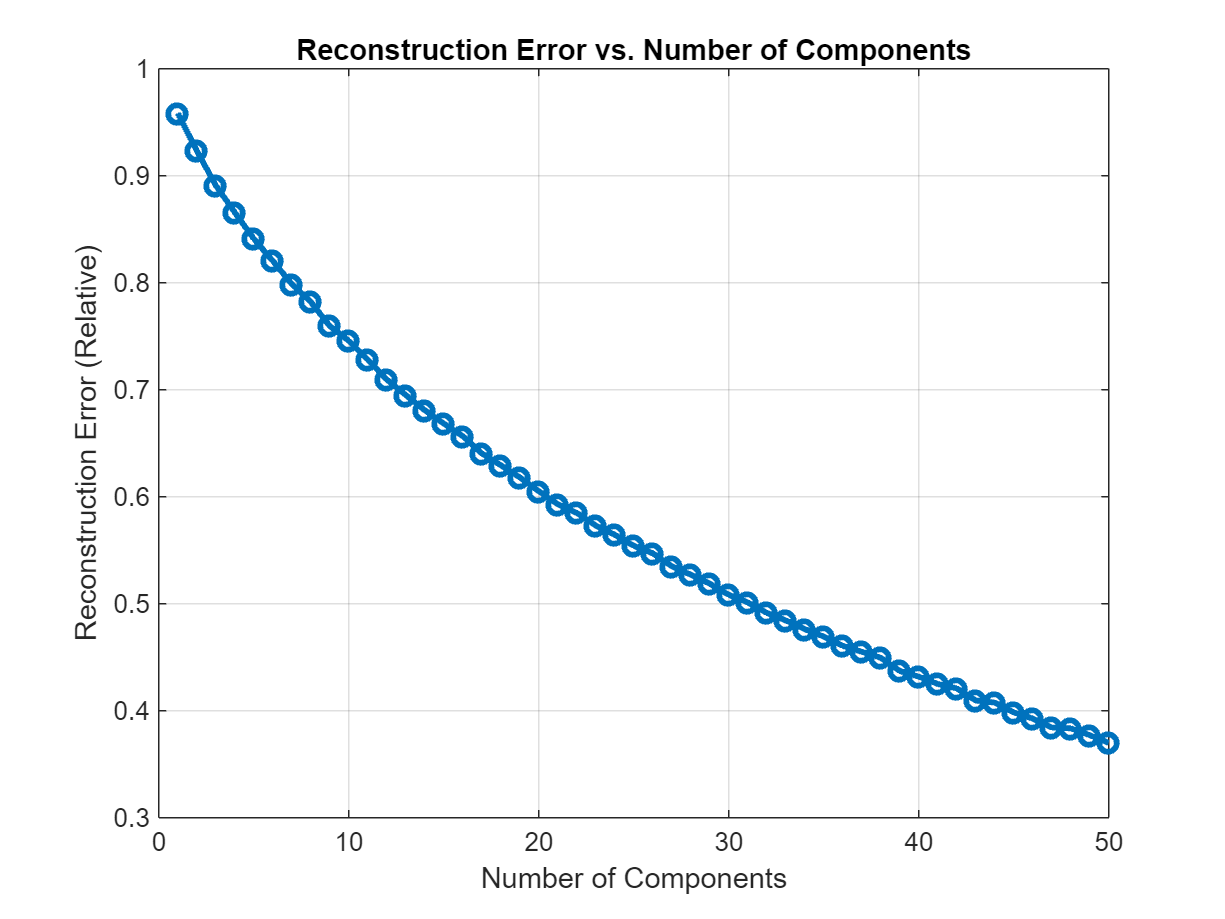

% Plot reconstruction error
figure;
plot(num_components, reconstruction_errors, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error vs. Number of Components');
grid on;

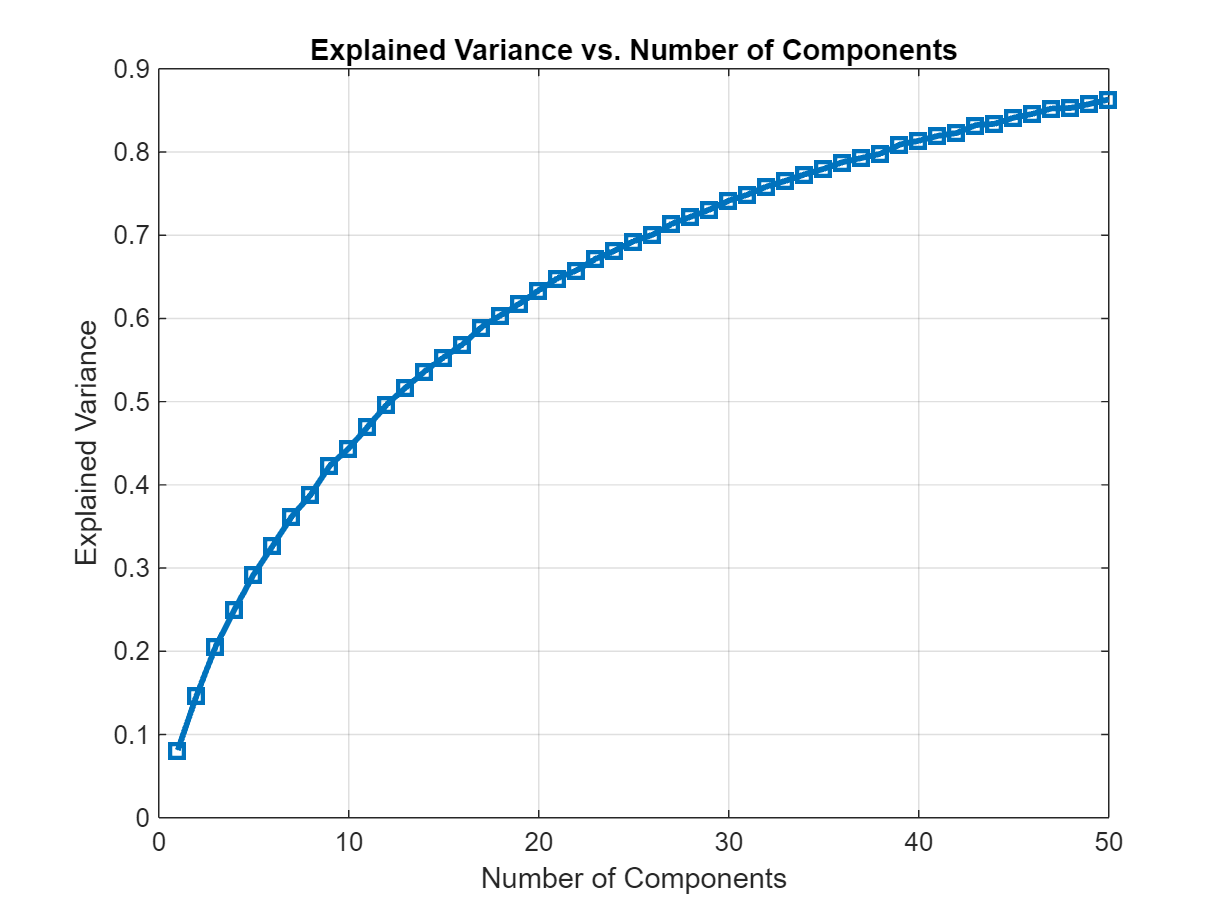


% Plot explained variance
figure;
plot(num_components, explained_variance, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance vs. Number of Components');
grid on;